%Jacob V Sanoj PES1UG20EC083
clc;
clear ;
close all;
b=input('Enter coefficients of x:');
a=input('Enter coefficients of y:');
M=length(b)-1;
N=length(a)-1;
IC=input('inital condiotions of y:');
n=[-N:20];
x=[(n>=0)]-[n>=2];
subplot(2,1,1)

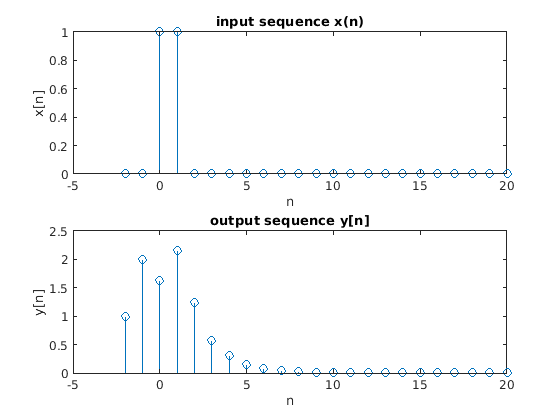

stem(n,x);
title('input sequence x(n)');
xlabel('n');
ylabel('x[n]');
y=[IC zeros(1,length(n)-N)];
for n=N+1:20
    sumx=0;
    sumy=0;
    
   for k=0:M
       sumx=sumx+(b(k+1)*x(n-k));
   end
   for k=1:N
       sumy=sumy+(a(k+1)*y(n-k));
   end
   y(n)=sumx-sumy;
end
n=[-N:20];
subplot(2,1,2);
stem(n,y);
title('output sequence y[n]');
xlabel('n');
ylabel('y[n]');

disp('y[n]=');

y[n]=


disp(y)

    1.0000    2.0000    1.6250    2.1562    1.2422    0.5801    0.3003    0.1476    0.0744    0.0371    0.0186    0.0093    0.0046    0.0023    0.0012    0.0006    0.0003    0.0001    0.0001    0.0000         0         0         0

